%Геометрические характеристики "кубика" ткани в мм
delta_Z=34.2;
l_mm = 10;
% Перевод в нужные единицы измерения
l = l_mm/1000;
% Удельное сопротивление крови в Ом*м
rho_blood = 1.35;
% исходное удельное сопротивление ткани в Ом*м
%rho_tissue0 = 1/0.13366;%серое вещество

%rho_tissue0 = 1/(60*10^(-3));%кожа
rho_tissue0 = 1/0.35;%мозг
%rho_tissue0 = 1/(0.020791);%лобная кость
% Плотность ткани в кг/м3
%rho_mech_tissue = 1000;
rho_mech_tissue = 1073;%мозг
%rho_mech_tissue = 925;%кожа
% Кровенаполнение ткани, мл/(мин*100г)
%V_blood_tissue = 10;
% ЧСС, уд/мин
HR = 60;
% Объём ткани
V_tissue = 0.1/rho_mech_tissue;
a = sqrt(V_tissue/l);
% Объём крови
%V_blood = (V_blood_tissue/HR)/1000000;
S_tissue = a*a;
%S_blood = V_blood/l;
%R_tissue = rho_tissue0*l/S_tissue;

% Закомментить когда обратный пересчёт
% R_blood = rho_blood*l/S_blood;
% R_blood_tissue = R_tissue*R_blood/(R_tissue+R_blood);
% deltaR = R_blood_tissue - R_tissue;
% b = sqrt(V_blood/l);
% %b = 0;
% % Изменение удельного сопротивления вследствие кровенаполнения
% delta__rho = (S_tissue)*deltaR/l;
% disp(delta__rho);
% Закомментить когда обратный пересчёт. Конец

%Обратный пересчёт в кровенаполнение на 100 г ткани
%Исходное значение изменения удельного сопротивления в Ом*м
coef1 = 31.33;%48.46;%31.33
coef2 = 0;%7.056;%12.55
delta_Z = 48.7-coef2*1000;%48.7
delta__rho = delta_Z/coef1/1000; % in Ohm*m

deltaR = delta__rho*l/S_tissue;
R_tissue = rho_tissue0*l/S_tissue;
R_blood_tissue = R_tissue+deltaR;
R_blood = R_blood_tissue*R_tissue/(R_tissue - R_blood_tissue);

S_blood = rho_blood*l/R_blood;
V_blood = S_blood*l*1000000;
deltaV = HR*V_blood% мл/мин на 100г

deltaV = -1.4367

%По Nyboer
%Расстояние между потенциальными электродами
theta = 58.2% градусов по окружности между потенциальными электродами

theta = 58.2000

r = 57/(2*pi)/100; % радиус головы по её охвату в м
deltaL = 2*r*sind(theta/2);
Z0 = 62% Ом базовое сопротивление

Z0 = 62

delV = rho_blood*deltaL^2*Z0^(-2)*delta_Z

delV = 9.3519e-05

delta_Z=(33.61)*10^(-3);%В Ом
%delta_Z = 60;
rho_mech_tissue = 1073;%мозг
rho_tissue0 = 1/0.15;%мозг
rho_blood = 1.35;
HR = 60;
k = 2.072;
delta_rho = -delta_Z/k;
%По выведенной формуле
deltaV = 0.1*delta_rho*rho_blood*HR/(rho_tissue0*rho_mech_tissue*(delta_rho-rho_tissue0))*1000000%мл

deltaV = 2.7485

f2=fit(rho_skin,imp_skin,'poly1')

f2 =      Linear model Poly1:
     f2(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       24.44  (24.41, 24.47)
       p2 =       20.45  (20.16, 20.74)

f3=fit(rho_brain,imp_brain,'poly1')

f3 =      Linear model Poly1:
     f3(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =       2.072  (2.072, 2.072)
       p2 =  -1.532e-05  (-2.468e-05, -5.965e-06)

imp_coeff = coeffvalues(f3)

imp_coeff =     2.0720   -0.0000


imp_fit = imp_coeff(1)*rho_brain+imp_coeff(2)

imp_fit =     0.4144
    0.6216
    0.8288
    1.0360
    1.2432
    1.4504
    1.6576
    1.8648
    2.0720
    2.2792


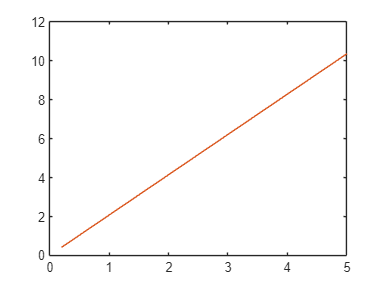

plot(rho_brain,imp_brain,LineStyle=":")
hold on
plot(rho_brain,imp_fit)
hold off

%По Nyboer
delta_Z=(150)*10^(-3);%В Ом
%Расстояние между потенциальными электродами
deltaL = 10/1000;
Z0 = 130% Ом базовое сопротивление

Z0 = 130

delV = rho_blood*deltaL^2*Z0^(-2)*delta_Z*1000000*60

delV = 0.0719

%delta_Z=(150)*10^(-3);%В Ом
rho_mech_tissue = 975;%мозг
rho_tissue0 = 1/0.15;%мозг
rho_blood = 1.35;
HR = 60;
%k = 24.44;
%delta_rho = (delta_Z)/k;
%По выведенной формуле
coef1 = 1.66;%48.46;%31.33
coef2 = 0;%7.056;%12.55
delta_Z = 105*10^(-3)-coef2;%48.7
delta__rho = delta_Z/coef1; % in Ohm*m
deltaV = 0.1*delta__rho*rho_blood*HR/(rho_tissue0*rho_mech_tissue*(delta__rho-rho_tissue0))*1000000%мл

deltaV = -11.9367

rho_mech_tissue = 1073;%мозг
rho_tissue0 = 1.5;%мозг
rho_blood = 1.35;
HR = 60;
deltaV = 54;

delta_rho = -rho_tissue0^2*rho_mech_tissue*deltaV*HR/(rho_mech_tissue*rho_tissue0*deltaV+10^5*rho_blood*HR)

delta_rho = -0.9554

rho_mech_tissue = 975;%кожа
rho_tissue0 = 17;%кожа
rho_blood = 1.35;
HR = 60;
deltaV = 8/1000000;

delta_rho = -rho_tissue0^2*rho_mech_tissue*deltaV*HR/(rho_mech_tissue*rho_tissue0*deltaV+0.1*rho_blood*HR)

delta_rho = -16.4288

rho_skin = 1:0.5:5

rho_skin =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000
